Image Segmentation

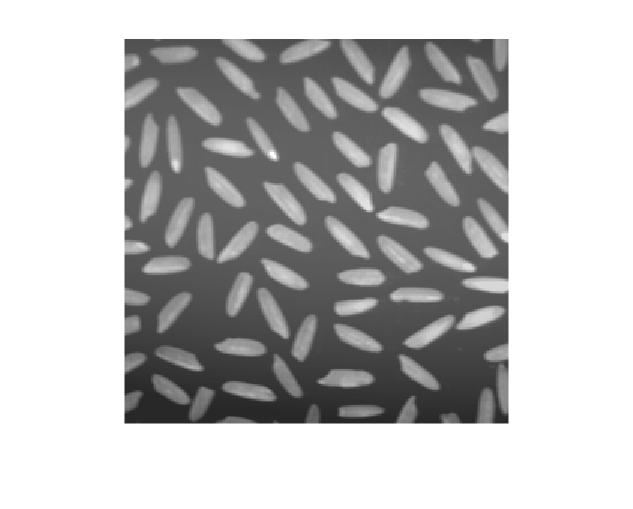

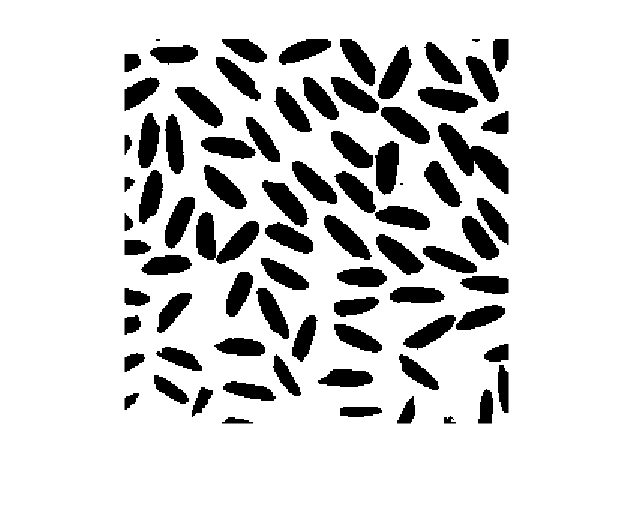

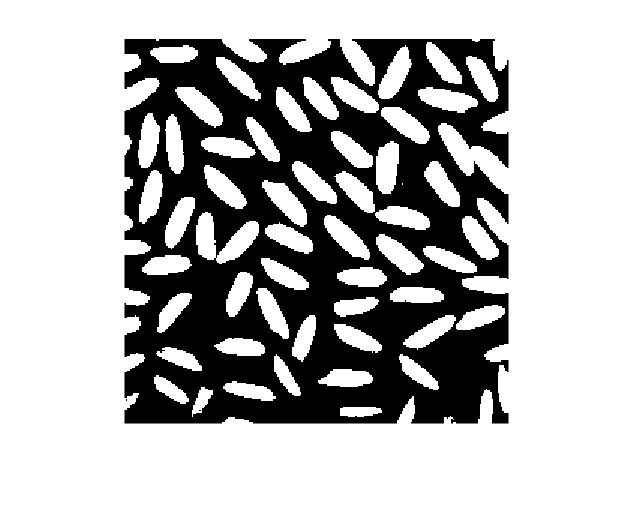

%Single Thresholding

r= imread('rice.tif');
imshow(r),figure, imshow(r<107),figure,imshow(r>107);

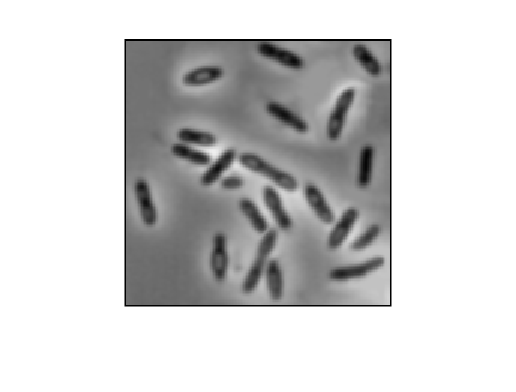

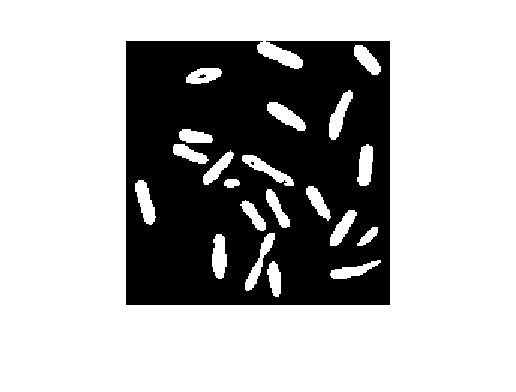

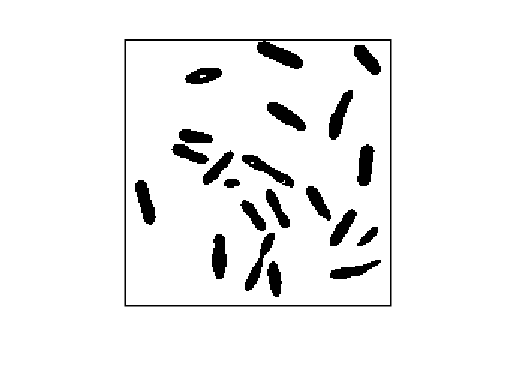

b = imread('bacteria.tif');
imshow(b),figure, imshow(b<100),figure,imshow(b>100);

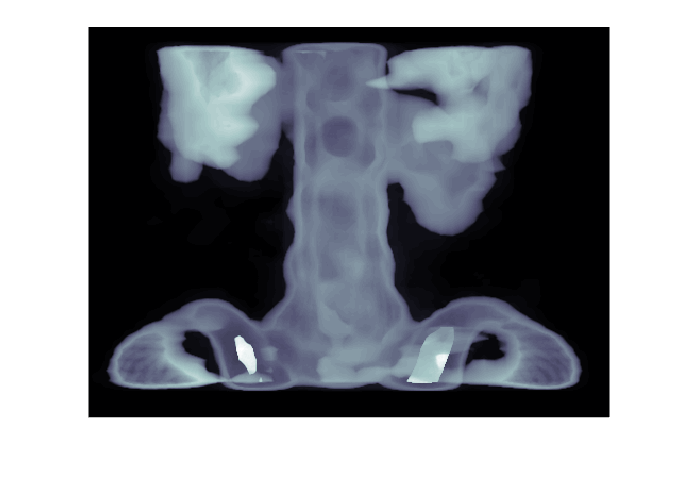

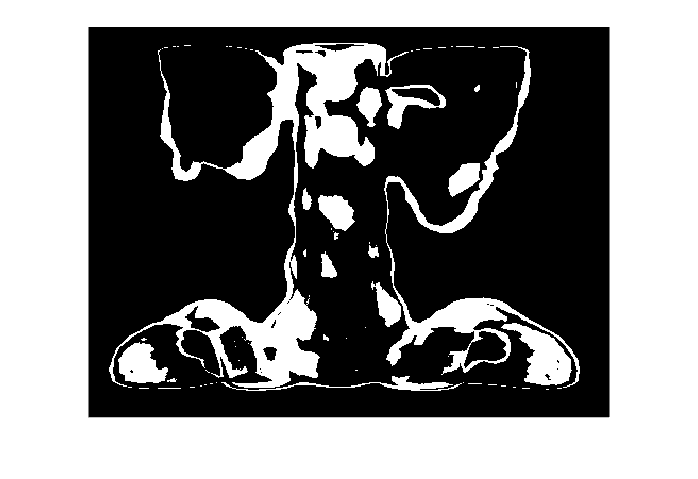

%Double thresholding

[s,lut] = imread('spine.tif');
imshow(s,lut),figure, imshow(s>20 & s<30);

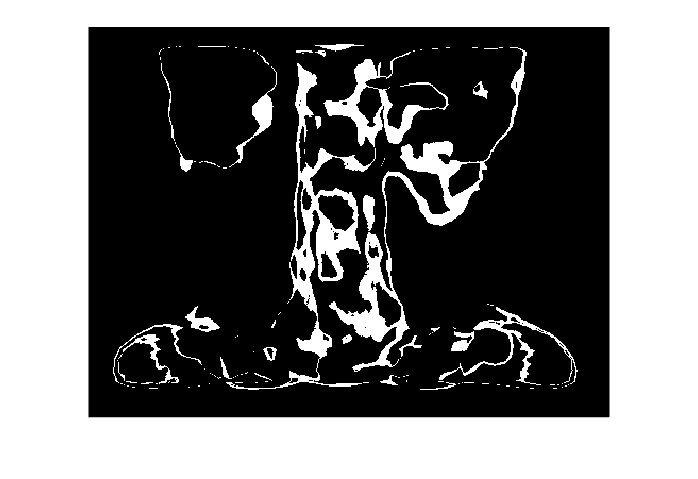


imshow(im2bw(s,lut,0.45) &~ im2bw(s,lut,0.50));

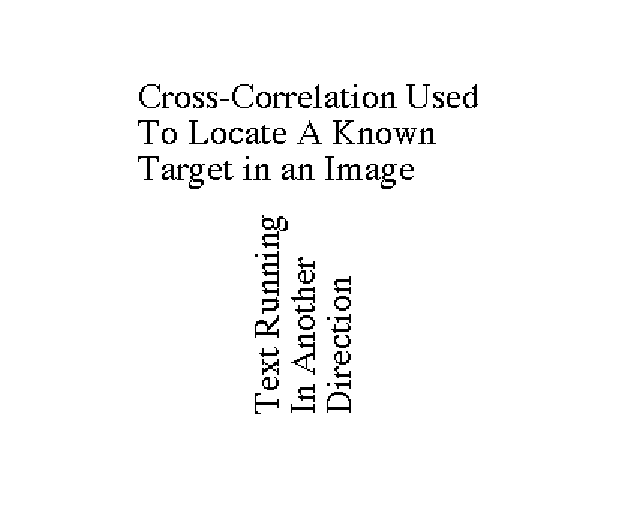

t = imread('text.tif');
% imshow(t),figure,imshow(t>125);

r= rand(256)*128 + 127;

tr = uint8(r .* double(not(t)));
imshow(tr>110);

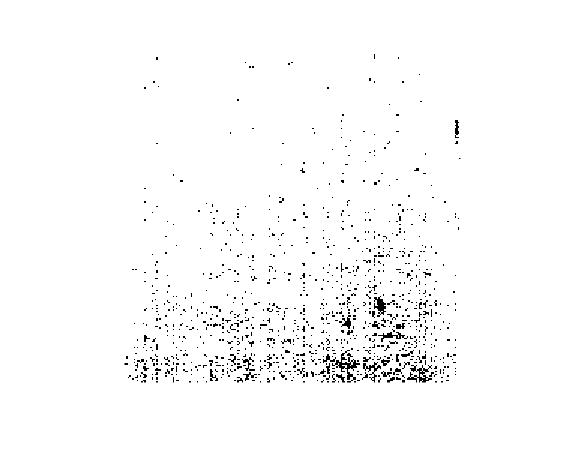

p = imread('paper.tif');
imshow(p>240);


ph = graythresh(p)

ph = 0.9471

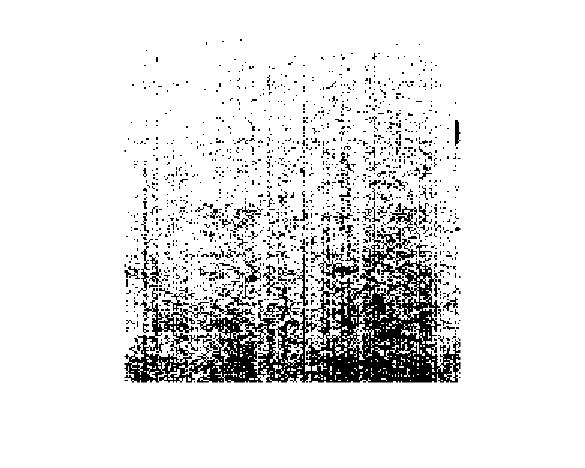


pbw = im2bw(p,ph);
imshow(pbw);